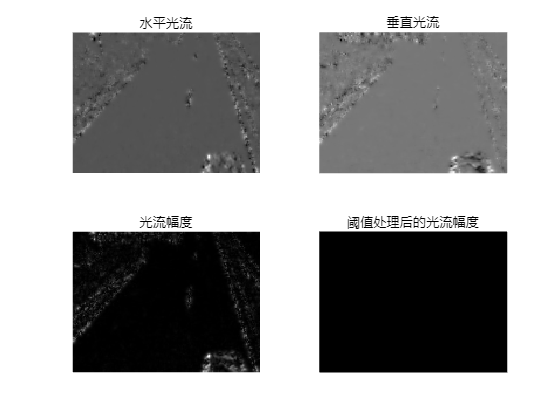

vidReader = VideoReader('viptraffic.avi');
% 光流
opticFlow = opticalFlowHS;
% 帧数
nFrames = 0;

figure;

while hasFrame(vidReader)
    frameRGB = readFrame(vidReader);
    frameGray = rgb2gray(frameRGB);
    flow = estimateFlow(opticFlow,frameGray);
    
    subplot(2,2,1);
    imshow(flow.Vx,[]);
    title('水平光流');
    
    subplot(2,2,2);
    imshow(flow.Vy,[]);
    title('垂直光流');
    
    flowMagnitude = sqrt(flow.Vx.^2 + flow.Vy.^2);
    subplot(2,2,3);
    imshow(flowMagnitude,[]);
    title('光流幅度');
    
    thresholdValue = 0.5; 
    binaryImage = flowMagnitude > thresholdValue;
    subplot(2,2,4);
    imshow(binaryImage);
    title('阈值处理后的光流幅度');
    
    pause(0.1);
    nFrames = nFrames + 1;
end

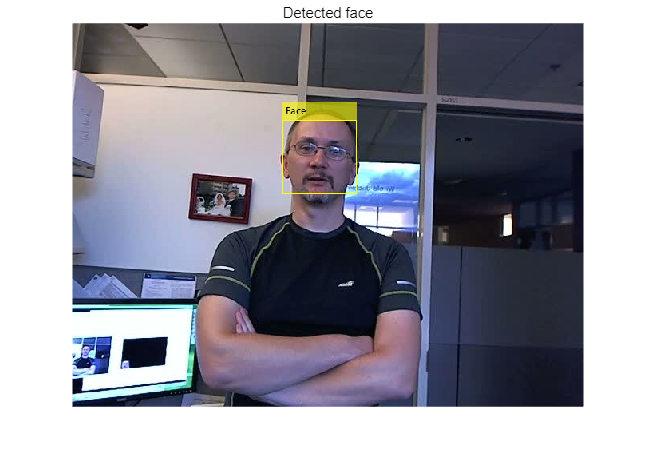

% Create a cascade detector object.
faceDetector = vision.CascadeObjectDetector();

% Use VideoReader instead of vision.VideoFileReader
videoFile = 'visionface.avi';
videoReader = VideoReader(videoFile);
videoFrame = readFrame(videoReader);
bbox = step(faceDetector, videoFrame);

% Draw the returned bounding box around the detected face.
videoOut = insertObjectAnnotation(videoFrame,'rectangle',bbox,'Face');
figure, imshow(videoOut), title('Detected face');

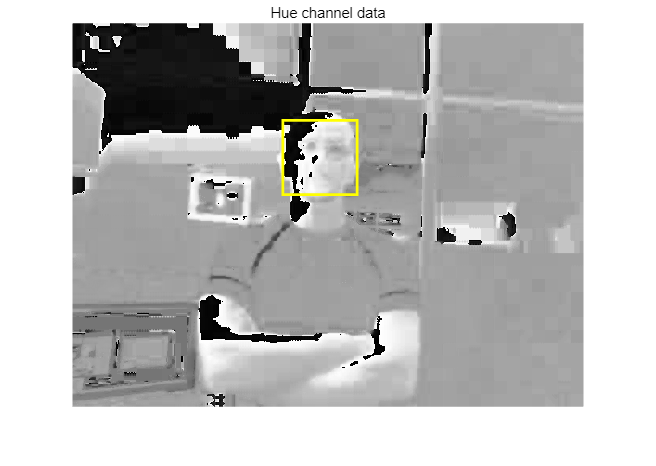


% Extract hue by converting to the HSV color space.
[hueChannel,~,~] = rgb2hsv(videoFrame);

% Display the hue channel data and draw the bounding box around the face.
figure, imshow(hueChannel), title('Hue channel data');
rectangle('Position',bbox(1,:),'LineWidth',2,'EdgeColor',[1 1 0])

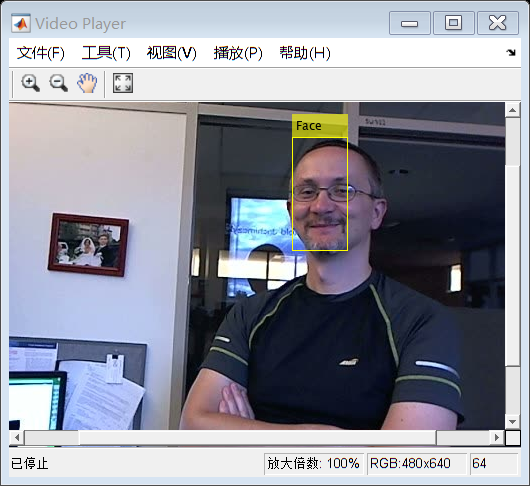


% CAMShift  algorithm
noseDetector = vision.CascadeObjectDetector('Nose', 'UseROI', true);
noseBBox = step(noseDetector, videoFrame, bbox(1,:));
% Create a tracker object.
tracker = vision.HistogramBasedTracker;

% Initialize the tracker histogram using the Hue channel pixels from the nose.
initializeObject(tracker, hueChannel, noseBBox(1,:));

% Create a video player object for displaying video frames.
videoPlayer = vision.VideoPlayer;

% Track the face over successive video frames until the video is finished.
while hasFrame(videoReader)
    
    % Extract the next video frame
    videoFrame = readFrame(videoReader);
    
    % RGB -> HSV
    [hueChannel,~,~] = rgb2hsv(videoFrame);
    
    % Track using the Hue channel data
    bbox = step(tracker, hueChannel);
    
    % Insert a bounding box around the object being tracked
    videoOut = insertObjectAnnotation(videoFrame,'rectangle',bbox,'Face');
    
    % Display the annotated video frame using the video player object
    step(videoPlayer, videoOut);
    
end

% Release resources
release(videoPlayer);

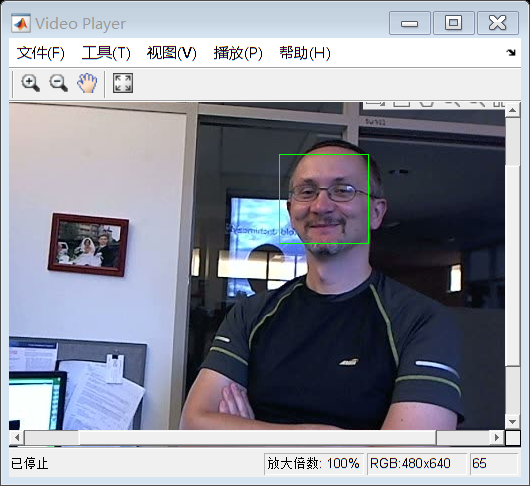

videoFile = 'visionface.avi';
vidObj = VideoReader(videoFile);

% Viola-Jones人脸检测器对象
faceDetector = vision.CascadeObjectDetector();

videoPlayer = vision.VideoPlayer();

while hasFrame(vidObj)
    frame = readFrame(vidObj);    
    grayFrame = rgb2gray(frame);    
    % 使用Viola-Jones检测器检测人脸
    bbox = step(faceDetector, grayFrame);
    
    detectedFrame = insertShape(frame, 'Rectangle', bbox, 'Color', 'green');
   
    step(videoPlayer, detectedFrame);
end

% 关闭视频播放窗口
release(videoPlayer);

load fisheriris;
for i=1:max(size(meas,2))
    t = meas(:,i);
    t = (t-min(t(:)))./(max(t(:))-min(t(:)));
    meas(:,i) = t;
end 

% 1 means 'virginica' and 0 means others
a = zeros(size(species));
for i = 1:max(size(a))
    a(i) = isequal(species{i},'virginica');
end  

cvo = cvpartition(a,'k',2);

% Split the data into two folds 
trIdx = cvo.training(1);  
teIdx = cvo.test(1);  

training_label_vector = a(trIdx); %ground truth  
training_instance_matrix = meas(trIdx, :); 

test_label_vector = a(teIdx);  %ground truth
test_instance_matrix = meas(teIdx, :); 

model = svmtrain(training_label_vector, training_instance_matrix, '-t 0');
[predict_label, accuracy, dec_values] = svmpredict(test_label_vector, test_instance_matrix, model);
fprintf('Classification Accuracy: %f%%\n', accuracy(1));

% confusion matrix
confusionMat = confusionmat(test_label_vector, predict_label);

% Calculate false positive rate and false negative rate
totalNegatives = sum(test_label_vector == 0);
totalPositives = sum(test_label_vector == 1);

FP = confusionMat(1, 2);  % False Positives
FN = confusionMat(2, 1);  % False Negatives

falsePositiveRate = FP / totalNegatives;
falseNegativeRate = FN / totalPositives;

fprintf('False Positive Rate: %f\n', falsePositiveRate);
fprintf('False Negative Rate: %f\n', falseNegativeRate);

%RBF核
model = svmtrain(training_label_vector, training_instance_matrix, '-t 2 -g 0.07');

%RBF-SVM对测试集进行分类
[predict_label, accuracy, dec_values] = svmpredict(test_label_vector, test_instance_matrix, model);

fprintf('Classification accuracy using RBF kernel: %f%%\n', accuracy(1));
g_values = [0.01, 0.03, 0.05, 0.07, 0.1, 0.5, 1];
best_accuracy = 0;
best_g = 0;

for g = g_values
    model = svmtrain(training_label_vector, training_instance_matrix, sprintf('-t 2 -g %f', g));
    [predict_label, accuracy, ~] = svmpredict(test_label_vector, test_instance_matrix, model);
    if accuracy(1) > best_accuracy
        best_accuracy = accuracy(1);
        best_g = g;
    end
    fprintf('Accuracy with g=%f: %f%%\n', g, accuracy(1));
end

fprintf('Best g value: %f with accuracy: %f%%\n', best_g, best_accuracy);
